### Init and load torque from excel:

clear
load("airfoil.mat")
load("wing_opt.mat")
load("scr_s0.mat")
load("Farror.mat")
data = load("Wing_Load_Positive.mat")

data = struct with fields:
    data: [60×4 table]


y0 = [-flip(data.data.Var1); data.data.Var1(2:end)];
S0 = [flip(data.data.Var2); data.data.Var2(2:end)];
M0 = [flip(data.data.Var3); data.data.Var3(2:end)];
tau0 = [flip(data.data.Var4); data.data.Var4(2:end)];

M = interp1(y0, M0, wing_opt.stripy,'spline');
tau = interp1(y0, tau0, wing_opt.stripy,'spline');
S = interp1(y0, S0, wing_opt.stripy,'spline');

pltidx=1

pltidx = 1

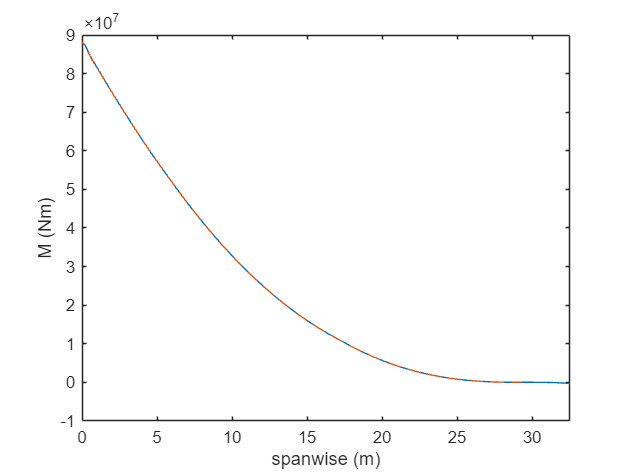

figure(pltidx)
clf;
plot(wing_opt.stripy, M)
hold on
plot(y0, M0,'--')
xlabel("spanwise (m)")
ylabel("M (Nm)")
xlim([0 wing_opt.b/2])

pltidx = pltidx + 1;

Material:

Al=material(); %Aluminum 2024 T861
Al.E = 72e9; %E - 72-75.7 GPa (@23degC is 73)
Al.sigma_y = 400e6; %sigma_y - 400-462 MPa (@23degC is 441)
Al.G = 28e9; %G - 28-29.4 GPa

## **WingBox geometry (unchanged throughout)**

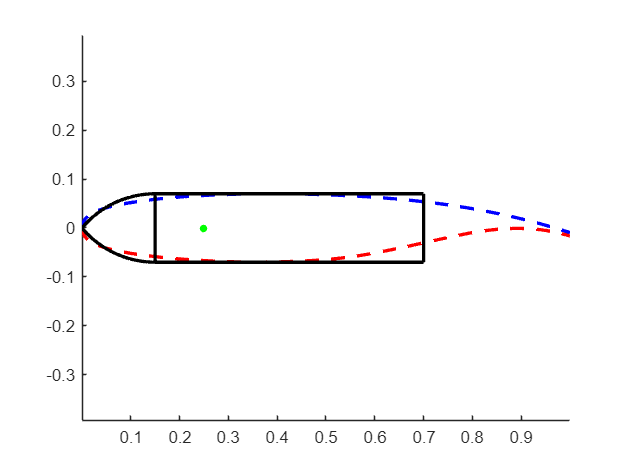

D = 6.38;
wb = wingbox();
%define geometry
wb.b2_c = 0.14;
wb.b_c = 0.15;
wb.c_c = 0.7 - wb.b_c;
wb = wb.calcR();
%define stringers
wb.L = 1;
%show wingbox:
figure(pltidx)
clf;
wb.drawwithAirfoil(airfoil)

pltidx = pltidx + 1;

wb = wb.calcCellArea(wing_opt);

%define rib spacing
wb.a = ones(1,length(wing_opt.stripy)).*5;
wingidx = find(wing_opt.stripy > D/2); % only consider points on the wing

spar geometry, flange

wb.t1_spar = 2e-3;
wb.t2_spar = 2e-3;
wb.b_spar = 10e-3;
wb = wb.createRibs(20, wing_opt, D, "uniform")

wb =   wingbox with properties:

        t_D: []
    t_Upper: []
    t_Lower: []
         tF: []
         tR: []
        c_c: 0.5500
       b1_c: []
        b_c: 0.1500
        R_c: 0.1957
          a: [5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 … ] (1×301 double)
       b2_c: 0.1400
         ts: []
         ds: []
         hs: []
         As: []
      sr_s0: []
          N: []
          F: []
    t1_spar: 0.0020
    t2_spar: 0.0020
     b_spar: 0.0100
         An: [0.1788 0.1852 0.1918 0.1985 0.2053 0.2122 0.2193 0.2264 0.2337 0.2411 0.2486 0.2562 0.2640 0.2718 0.2798 0.2878 0.2960 0.3043 0.3128 0.3213 0.3299 0.3387 0.3476 0.3566 0.3657 0.3749 0.3843 0.3937 0.4033 0.4130 0.4228 … ] (1×301 double)
         Ar: [0.9432 0.9774 1.0121 1.0475 1.083

wb = wb.mapRibSpacing(wing_opt, D)

wb =   wingbox with properties:

        t_D: []
    t_Upper: []
    t_Lower: []
         tF: []
         tR: []
        c_c: 0.5500
       b1_c: []
        b_c: 0.1500
        R_c: 0.1957
          a: [5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 … ] (1×301 double)
       b2_c: 0.1400
         ts: []
         ds: []
         hs: []
         As: []
      sr_s0: []
          N: []
          F: []
    t1_spar: 0.0020
    t2_spar: 0.0020
     b_spar: 0.0100
         An: [0.1788 0.1852 0.1918 0.1985 0.2053 0.2122 0.2193 0.2264 0.2337 0.2411 0.2486 0.2562 0.2640 0.2718 0.2798 0.2878 0.2960 0.3043 0.3128 0.3213 0.3299 0.3387 0.3476 0.3566 0.3657 0.3749 0.3843 0.3937 0.4033 0.4130 0.4228 … ] (1×301 double)
         Ar: [0.9432 0.9774 1.0121 1.0475 1.083

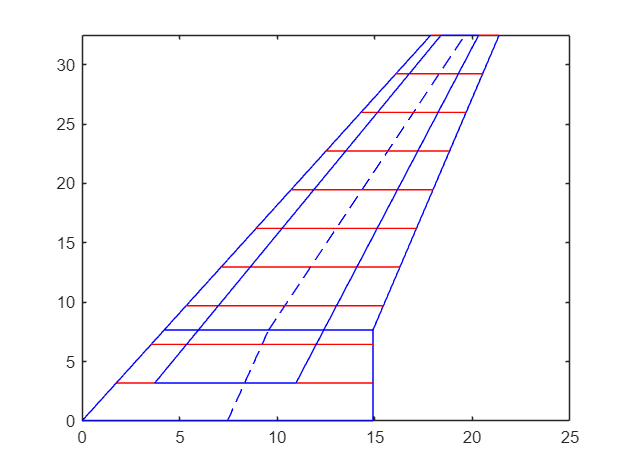


figure(pltidx)
clf;
pltidx = pltidx + 1;
wing_opt.plotWing
hold on
wb.plotRibs(wing_opt)
hold on
wb.plotWingBox(wing_opt,D)
ylim([0 wing_opt.b/2])

## 1.UpperPanel Design

To get a high Farror ratio 0.95:

ts/t = 1.05

As/b1 t = 1.5

wb.hs = 60e-3;    % stringer height
wb.ts = 15e-3;    % stringer thickness
N1 = 30;
N2 = 16;
N3 = 8;
x = [wb.hs, wb.ts, N1, N2, N3];
d_hratio = 0.3;
wb.N = [N3*ones(1,50) N2*ones(1,50) N1*ones(1,50) 0 N1*ones(1,50) N2*ones(1,50) N3*ones(1,50)];        % stringer number
wb.t_Upper = wb.ts/1.05; % main cell thickness
wb.ds = wb.hs*d_hratio;% stringer width
wb = wb.calcb1(D, wing_opt);
wb = wb.calcStringerArea();
wb = wb.interpsr_s0(scr_s0,wing_opt);
wb = wb.interpretF(F_data, wing_opt);
%val to minimise: error between wb.As ./ (wb.b1_c .* wing_opt.cn) ./
%wb.t_Upper and yline(1.5)

% three sections of number of stringers

Optimization code:

function err = objective_Upanel(x, wing_opt, wb, D)
    % Extract variables
    hs = x(1);
    ts = x(2);
    N1 = x(3);
    N2 = x(4);
    N3 = x(5);
    
    % Update wb properties that ARE fields
    wb.hs = hs;   % Update hs (field of wb)
    wb.ts = ts;   % Update ts (field of wb)
    
    % Construct wb.N from N1/N2/N3 (not fields of wb)
    wb.N = [N3*ones(1,50), N2*ones(1,50), N1*ones(1,50), 0, ...
            N1*ones(1,50), N2*ones(1,50), N3*ones(1,50)];
    
    % Calculate dependent properties
    wb = wb.calcb1(D, wing_opt);
    wb = wb.calcStringerArea();
    
    % Compute error
    target = 1.5;
    current_val = wb.As ./ (wb.b1_c .* wing_opt.cn .* wb.t_Upper);
    wingidx = find(abs(wing_opt.stripy) > D/2); % only consider points on the wing
    err = sum((current_val(wingidx) - target).^2);
end

function [optimized_wb, N1_opt, N2_opt, N3_opt] = optimize_Upanel(wing_opt, wb, D, N1_init, N2_init, N3_init)
    % Initial guess: [hs, ts, N1, N2, N3]
    x0 = [wb.hs, wb.ts, N1_init, N2_init, N3_init];
    
    % Bounds for variables
    lb = [10e-3,  5e-3, 10, 10, 10];
    ub = [1009e-3, 1009e-3, 100, 100, 100];
    
    % Define objective function
    fun = @(x) objective_Upanel(x, wing_opt, wb, D);
    
    % Run optimization (using fmincon)
    options = optimoptions('fmincon', 'Display', 'iter');
    [x_opt, ~] = fmincon(fun, x0, [], [], [], [], lb, ub, [], options);
    
    % Update the wb structure with optimized parameters
    optimized_wb = wb; 
    optimized_wb.hs = x_opt(1);  % Update hs (field of wb)
    optimized_wb.ts = x_opt(2);  % Update ts (field of wb)
    
    % Extract optimized N1/N2/N3 (not fields of wb)
    N1_opt = round(x_opt(3));
    N2_opt = round(x_opt(4));
    N3_opt = round(x_opt(5));
    
    % Rebuild wb.N with optimized values
    optimized_wb.N = [N3_opt*ones(1,50), N2_opt*ones(1,50), N1_opt*ones(1,50), 0, ...
                     N1_opt*ones(1,50), N2_opt*ones(1,50), N3_opt*ones(1,50)];
    optimized_wb = optimized_wb.calcb1(D, wing_opt);
    optimized_wb = optimized_wb.calcStringerArea();
end

[wb, N1, N2, N3] = optimize_Upanel(wing_opt, wb, D, N1, N2, N3)

Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    3.195005e+02    0.000e+00    1.620e+04
    1      16    2.506567e+01    0.000e+00    1.965e+01    9.958e-02
    2      22    1.728502e+01    0.000e+00    3.794e+03    3.501e+00
    3      28    1.588286e+01    0.000e+00    1.550e+02    3.111e+00
    4      35    1.422304e+01    0.000e+00    1.726e+03    7.948e-01
    5      44    1.331864e+01    0.000e+00    4.230e+02    1.119e+00
    6      50    1.312236e+01    0.000e+00    4.799e+02    1.119e+00
    7      58    1.308026e+01    0.000e+00    1.254e+02    6.909e-01
    8      64    1.293422e+01    0.000e+00    5.077e+00    7.856e-01
    9      70    1.292407e+01    0.000e+00    6.375e-01    1.347e-01
   10      76    1.292404e+01    0.000e+00    8.269e-01    9.574e-03
   11      82

wb =   wingbox with properties:

        t_D: []
    t_Upper: 0.0143
    t_Lower: []
         tF: []
         tR: []
        c_c: 0.5500
       b1_c: [0.0239 0.0240 0.0240 0.0241 0.0241 0.0242 0.0242 0.0243 0.0243 0.0244 0.0244 0.0245 0.0245 0.0245 0.0246 0.0246 0.0246 0.0247 0.0247 0.0247 0.0248 0.0248 0.0248 0.0249 0.0249 0.0249 0.0250 0.0250 0.0250 0.0250 0.0251 … ] (1×301 double)
        b_c: 0.1500
        R_c: 0.1957
          a: [5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 … ] (1×301 double)
       b2_c: 0.1400
         ts: 0.0181
         ds: 0.0180
         hs: 0.0987
         As: 0.0024
      sr_s0: [1.3945 1.3947 1.3949 1.3951 1.3953 1.3955 1.3950 1.3943 1.3937 1.3930 1.3924 1.3899 1.3856 1.3814 1.3774 1.3735 1.3704 1.3677 1.3652 1.36

N1 = 56

N2 = 41

N3 = 22

pltidx = 1;

d_hratio = 0.3;
wb.N = [N3*ones(1,50) N2*ones(1,50) N1*ones(1,50) 0 N1*ones(1,50) N2*ones(1,50) N3*ones(1,50)];        % stringer number
wb.t_Upper = wb.ts/1.05; % main cell thickness
wb.ds = wb.hs*d_hratio;% stringer width
wb = wb.calcb1(D, wing_opt);
wb = wb.calcStringerArea();
wb = wb.interpsr_s0(scr_s0,wing_opt);
wb = wb.interpretF(F_data, wing_opt);

wbStress = wingboxStress();
wbStress.wb = wb;
wbStress = wbStress.findGlobalStress(M,wing_opt,Al, wb.t_Upper);
wbStress = wbStress.findLocalStress(M,wing_opt,Al);

Thickness parameters need to be optimized to give equal global and local buckling stress

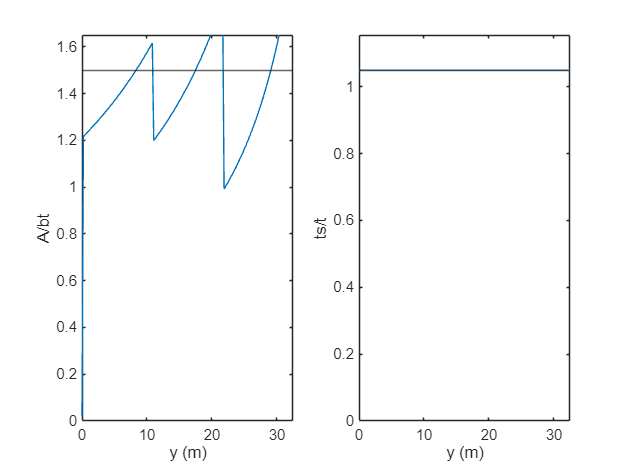

figure(2)
clf;
subplot(1,2,1)
xq = wb.As ./ (wb.b1_c .* wing_opt.cn) ./ wb.t_Upper;
yq = wb.ts/wb.t_Upper.*ones(size(xq));
plot(wing_opt.stripy,xq)
hold on
yline(1.5)
ylabel("A/bt")
xlabel("y (m)")
xlim([0 wing_opt.b/2])
ylim([0 1.5*1.1])

subplot(1,2,2)
plot(wing_opt.stripy,yq)
hold on
yline(1.05)
ylabel("ts/t")
xlabel("y (m)")
xlim([0 wing_opt.b/2])
ylim([0 1.05*1.1])

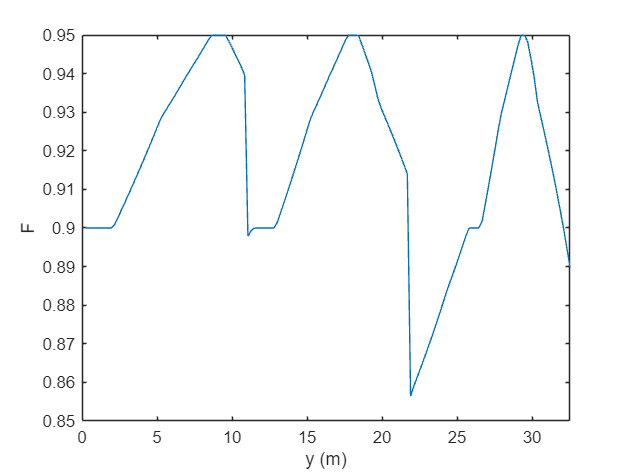



figure(3)
clf;
plot(wing_opt.stripy,wb.F)
ylabel("F")
xlabel("y (m)")
xlim([0 wing_opt.b/2])


figure(4)
clf;
pltidx = pltidx + 1;
hold on
plot(wing_opt.stripy(wingidx), wbStress.s_cr_global_skin(wingidx)*1e-6);
hold on
plot(wing_opt.stripy(wingidx), wbStress.s_cr_local_skin(wingidx)*1e-6);

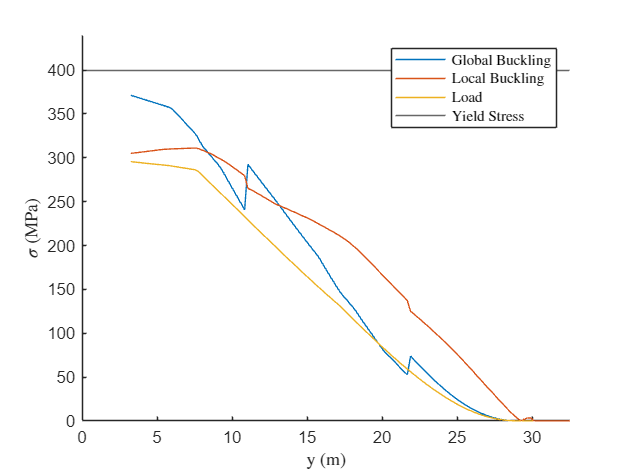

hold on
c = wb.c_c.*wing_opt.cn;
b2 = wb.b2_c.*wing_opt.cn;
N = M./c./b2;
plot(wing_opt.stripy(wingidx),N(wingidx)./wb.t_Upper*1e-6)
hold on
yline(Al.sigma_y*1e-6)
legend("Global Buckling","Local Buckling","Load","Yield Stress","Interpreter","latex")
xlabel("y (m)","Interpreter","latex")
ylabel("$\sigma$ (MPa)","Interpreter","latex")
xlim([0 wing_opt.s])
ylim([0 Al.sigma_y*1e-6*1.1])

## **2. Spar buckling analysis(get spar thickness)**

**Web is fixed at top/bottom, SS at sides (web stringers)**

[t_FS, t_RS] = Sparfun(wb, wing_opt,material,V,T,wbStress)

Unrecognized function or variable 'V'.

## 3. Dcell

%guessed D cell skin thickness
t1 = 0.01;
t = Dcellfun(wb,wing_opt,wing_opt.b/2,Al,t1,9)

## **4. Rib**

[thickness_buckling, thickness_yield]= Ribfun(20e-3,M,wing_opt,wb,Al,1e-3)

## 5. Box

P = rand(size(M))
[tau_n, tau_r, tau_w, sigmax] = boxfun(wb, wing_opt, P, M, Al)